## Import Data

clear all;
clc;
data = readtable("step_osc_150ohm.csv");
data = fillmissing(data,'nearest');
data([1,2],:) = []

data = 1280×3 table
     Var1       Var2       Var3  
    _______    ______    ________

         -5    9.0755    0.015154
    -4.9961    9.0755    0.015154
    -4.9922    9.0755    0.012641
    -4.9883    9.0755    0.012641
    -4.9844    9.0755    0.012641
    -4.9805    9.0755    0.012641
    -4.9766    9.0755    0.012641
    -4.9727    9.0755    0.012641
    -4.9688    9.0755    0.012641
    -4.9648    9.0755    0.012641
    -4.9609    9.0755    0.012641
     -4.957    9.0755    0.012641
    -4.9531    9.0755    0.012641
    -4.9492    9.0755    0.012641
    -4.9453    9.0755    0.012641
    -4.9414    9.0755    0.015154


## Assign Variables

% Seperate values
t = table2array(data(:,1))+5;
Vout = table2array(data(:,2));
D = table2array(data(:,3));

% Match to duty cycle
D = round(D/5)*10+50;       

% Find index before step
idx = find(D<60,1,'last');

% Trim data with new index
t = t(idx-9:end);
Vout = Vout(idx-9:end);
D = D(idx-9:end);

% Reset time and find sampling time
t = t-t(1);
T_s=t(2)-t(1)

T_s = 0.0039

## Identify Transfer Functions

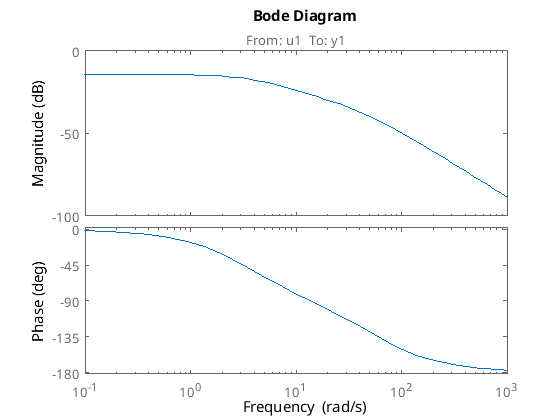

idd = iddata(Vout,D,T_s);
G=tfest(idd,2,0);
bode(G)

gm = 60; Ni=5; alpha=0.5;
[wc, Kp, taui, taud, ok] = findpid(G,gm,Ni,alpha)

ans = 'Found 1 valid solution(s) out of 1 phase crossing(s)'

wc = 48.1552

Kp = 63.7188

taui = 0.1038

taud = 0.0294

ok = 1

s=tf('s');
Cpid=Kp*(taud*s+1)/(alpha*taud*s+1)*(taui*s+1)/(taui*s)

Cpid =
 
  0.1943 s^2 + 8.487 s + 63.72
  ----------------------------
    0.001525 s^2 + 0.1038 s
 
Continuous-time transfer function.



Cpid = minreal(Cpid)

Cpid =
 
  127.4 s^2 + 5567 s + 4.179e04
  -----------------------------
          s^2 + 68.1 s
 
Continuous-time transfer function.



Gol=minreal(G*Cpid)

Gol =
 
  From input to output "y1":
     4773 s^2 + 2.085e05 s + 1.565e06
  ---------------------------------------
  s^4 + 124.3 s^3 + 4016 s^2 + 1.297e04 s
 
Continuous-time transfer function.



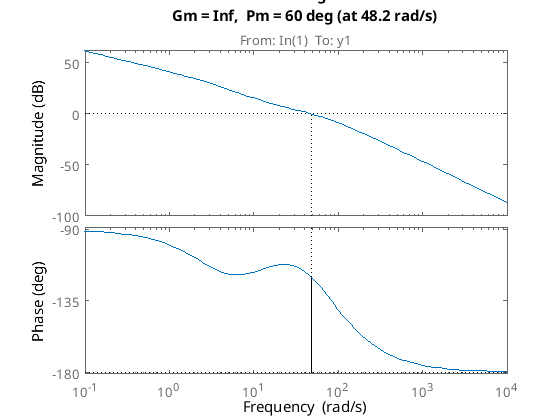

margin(Gol);

## Z-Transform

Gz=c2d(Cpid,1/10e3,'tustin');
Gz.Variable='z^-1'

Gz =
 
  127.3 - 254 z^-1 + 126.7 z^-2
  -----------------------------
  1 - 1.993 z^-1 + 0.9932 z^-2
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



## Discrete Implementation


$$y_i =127\ldotp 3\cdot u_i -254\cdot u_{i-1} +126\ldotp 7\cdot u_{i-2} +1\ldotp 993\cdot y_{i-1} -0\ldotp 9932\cdot y_{i-2}$$


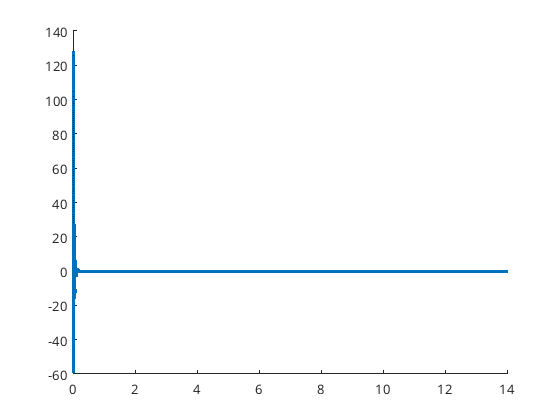

% Build time vector
dt=1/10e3;
t = 0:dt:14;

% Build step input
u = ones(size(t));
u(1)=0;

% Initialize variables
uk_1=0;
uk_2=0;
yk_1=0;
yk_2=0;

% Step through time and solve the difference equation
for i = 1:length(t)
    if i == 1
        uvals = 127.3*u(i) - 254*uk_1 + 126.7*uk_2;
        yvals = 1.993*yk_1 - 0.9932*yk_2;
        y(i) = uvals + yvals;
    elseif i == 2
        uvals = 127.3*u(i) - 254*u(i-1) + 126.7*uk_2;
        yvals = 1.993*y(i-1) - 0.9932*yk_2;
        y(i) = uvals + yvals;
    else
        uvals = 127.3*u(i) - 254*u(i-1) + 126.7*u(i-2);
        yvals = 1.993*y(i-1) - 0.9932*y(i-2);
        y(i) = uvals + yvals;
    end
end

scatter(t,y,3)

1/(20/(20+80))

ans = 5